# Exercise 9

## 1. Histogram Equalization for Color Images

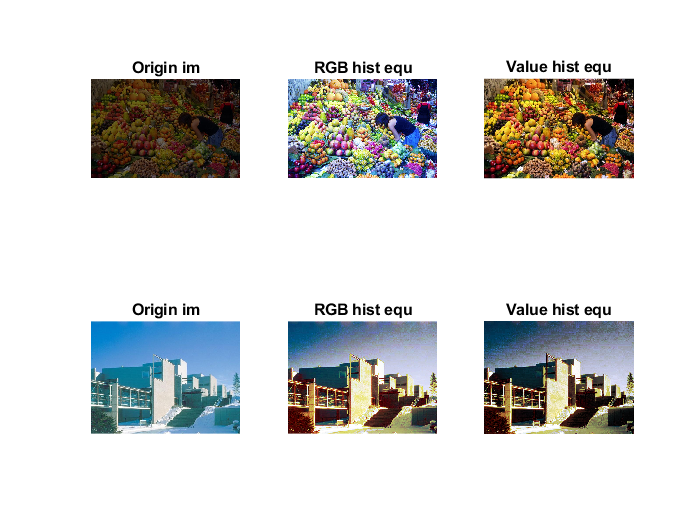

%a
i = imread('fruits.jpg');
i_r = i(:,:,1);
i_g = i(:,:,2);
i_b = i(:,:,3);

%imshow(i_r);title('Red component')
i_r_hist = histeq(i_r);

%imshow(i_g);title('Green component')
i_g_hist = histeq(i_g);

%imshow(i_b);title('Blue component')
i_b_hist = histeq(i_b);

result_1 = uint8(cat(3,i_r_hist,i_g_hist,i_b_hist));
%b
%c
fe = imread('festia.jpg');
fe_r = fe(:,:,1);
fe_g = fe(:,:,2);
fe_b = fe(:,:,3);
% figure,
% subplot(3,2,1)
% imshow(fe_r);title('Red component')
% subplot(3,2,2)
fe_r_hist = histeq(fe_r);

% subplot(3,2,3)
% imshow(fe_g);title('Green component')
% subplot(3,2,4)
fe_g_hist = histeq(fe_g);

% subplot(3,2,5)
% imshow(fe_b);title('Blue component')
% subplot(3,2,6)
fe_b_hist = histeq(fe_b);
result_2 = uint8(cat(3,fe_r_hist,fe_g_hist,fe_b_hist));

figure,
subplot(2,3,1)
imshow(i);title('Origin im')
subplot(2,3,2)
imshow(result_1),title('RGB hist equ');
subplot(2,3,3)
intensityeq(i),title('Value hist equ')
subplot(2,3,4)
imshow(fe),title('Origin im');
subplot(2,3,5)
imshow(result_2),title('RGB hist equ')
subplot(2,3,6)
intensityeq(result_2),title('Value hist equ')

## 2.Object Extraction

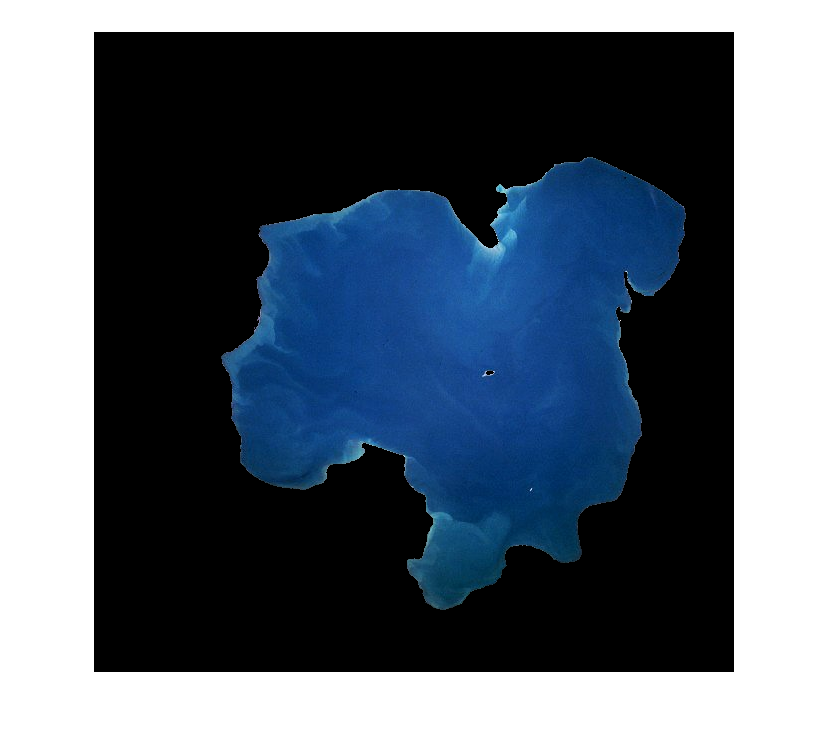

i1 = imread('lake.jpg');
i_gray = rgb2hsv(i1);
% doc graythresh
% doc imbinarize
% doc bwlabel

%computes a global threshold 'levlel' from grayscale image i_gray
% using Otsu's method
level = graythresh(i_gray);
%creates a binary image from image i_gray using the threshold value 'level'.
bw = im2bw(i_gray,level);
% returns the label matrix L that contains labels 
% for the 8-connected objects found in BW.
L = bwlabel(bw,8);
imshow(L);
results = uint8(zeros(size(i1)));
for x =1:size(i1,1)
    for y =1:size(i1, 2)
        if L(x, y) == 716
            results(x, y,:)=i1(x, y,:);
        end
    end
end

figure,
imshow(results)